% Load Data
clc;
clear; 


% Reads the complied excel for all motors as a table. If new motors are inputted in the table it
% should still work.
data = readtable('Motors_Compiled.csv', "Delimiter", ',' ); 


D = struct("Motor_Name", {data.Motor_Name}, "Prop_D", data.PropD, "Thrust50", data.Thrust50, "Thrust100", data.Thrust100, ...
    "Current50", data.Current50, "Current100", data.Current100, "Power50", data.Power50, "Power100", data.Power100, "Weight", data.Weight_g_); 

D.Motor_Name(1)

ans = 1×1 cell array
    {'KDE3520XF-400'}


D.Prop_D(1)

ans = 15.5000

D.Thrust50(1)

ans = 550

D.Thrust100(1)

ans = 1810

D.Current50(1)

ans = 2.4000

D.Current100(1)

ans = 12.4000

D.Power50(1)

ans = 41

D.Power100(1)

ans = 215

D.Weight(1)

ans = 245


% Example for naming scheme, using the same parameter gives you the motor and all of its stats. 
% Think of the input number as row selection across the whole motor compiled sheet and
% the columns are sections by data type
%
%
% D.Motor_Name(1) --> refers to the motor names column, and the 1 is the
% row number which is the first motor in the sheet. If you want data
% referring to this motor, input the data type you are interested in and
% include a 1 as the parameter. 
%


## Conversion



D.Thrust50 = D.Thrust50 * 9.8 / 1000; % gram force --> Newtons
D.Thrust100 = D.Thrust100 * 9.8 / 1000;  % gram force --> Newtons
D.Weight = D.Weight/1000 % g --> kg 

D = struct with fields:
    Motor_Name: {31×1 cell}
        Prop_D: [31×1 double]
      Thrust50: [31×1 double]
     Thrust100: [31×1 double]
     Current50: [31×1 double]
    Current100: [31×1 double]
       Power50: [31×1 double]
      Power100: [31×1 double]
        Weight: [31×1 double]


## Thrust to Propeller Graph

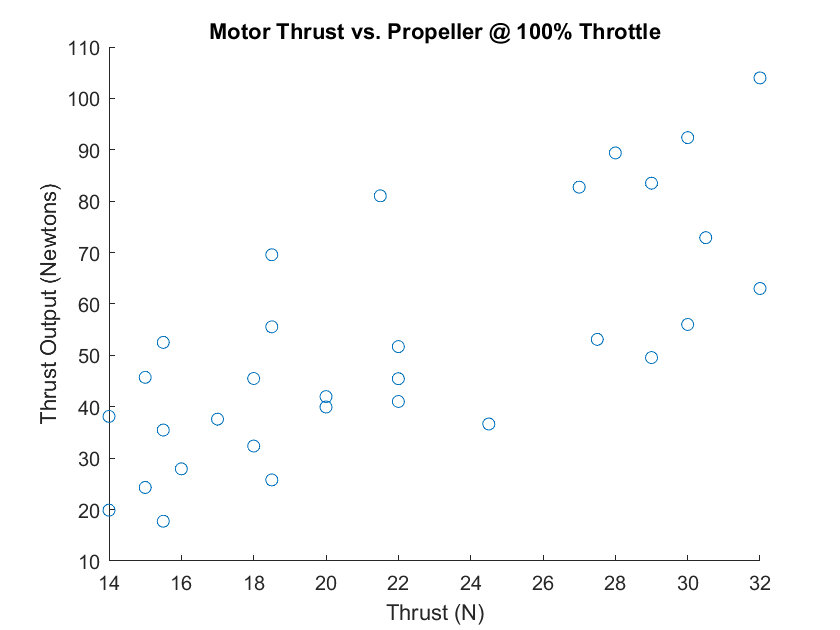


    figure(1)
    Thrust = D.Thrust100; % convert grams to Newtons
    P = D.Prop_D;
    hold on
    title('Motor Thrust vs. Propeller @ 100% Throttle')
    xlabel('Thrust (N)')
    ylabel(['Thrust Output (Newtons)']) 
    scatter(P,Thrust)
    hold off

## Subset passing thrust limit

    Payload = 25 % lbs 

Payload = 25

    BatteryW = 3 % kg

BatteryW = 3

    
    % Conversion
    Payload = Payload*0.453592; % lb -> kg conversion
    
    count = 1; 
    for i = 1:height(data)
        %% DownForce
        TotalDownForce = (Payload+(8*D.Weight(i))+BatteryW)*9.8*1.2; % Ensure this includes *8 for 8 motors
        MAXThrustEst = TotalDownForce*2 ;
        Thrust_Threshold = MAXThrustEst/8;
        
        if (D.Thrust100(i) > Thrust_Threshold)
            motorpass(count) = i; 
            count = count + 1; 
        end
    end
    

## Graph Passing Subset

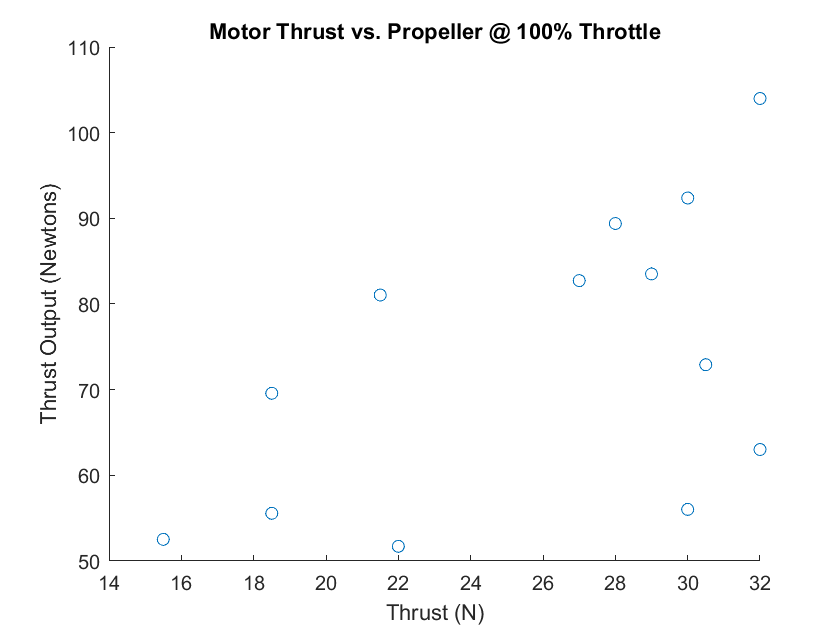

    figure(2)
    Thrust = D.Thrust100(motorpass); % convert grams to Newtons
    P = D.Prop_D(motorpass);
    hold on
    title('Motor Thrust vs. Propeller @ 100% Throttle')
    xlabel('Thrust (N)')
    ylabel(['Thrust Output (Newtons)'])
    scatter(P,Thrust)
    hold off

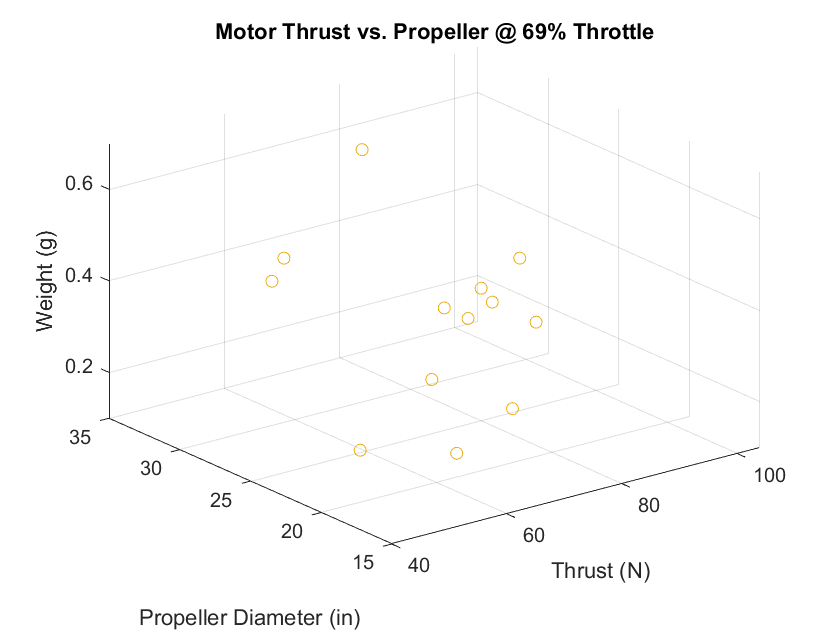

    
    figure(3)
    view(3)
    X = D.Thrust100(motorpass); % convert grams to Newtons
    Y = D.Prop_D(motorpass);
    Z = D.Weight(motorpass);
    hold on
    title('Motor Thrust vs. Propeller @ 100% Throttle')
    xlabel('Thrust (N)')
    ylabel('Propeller Diameter (in)')
    zlabel('Weight (g)')
    grid on 
    plot3(X, Y, Z, 'o')

    
    
%% Subset weight order

    
    
    
    
    
    
    
    
    
    